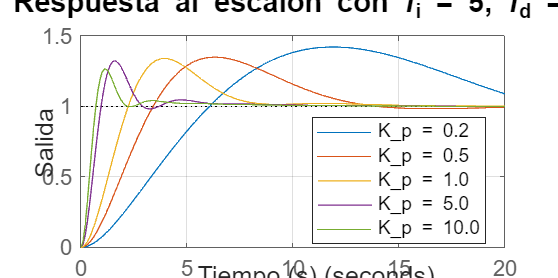

% PID_analisis_Kp.m
close all;
clear;
clc;

% Parámetros del sistema
K = 2652.28;
p = 64.986;
tau_i = 5;
tau_d = 0.2;
t = 0:0.1:20;

% Valores de Kp a analizar
%Kp_vals = [0.2, 0.5, 1, 5, 10];

% Figura 1: respuesta al escalón
fig1 = figure('Units', 'centimeters', 'Position', [2, 2, 20, 10]);
hold on;

for i = 1:length(Kp_vals)
    Kp = Kp_vals(i);
    
    % Numerador del PID-D
    num_PID_D = K*Kp*[1, 1/tau_i];
    
    % Denominador: suma de s^2*(s+p) y controlador
    den_planta = conv([1 0 0], [1 p]);
    den_control = K*Kp*tau_d * [1, 1/tau_d, 1/(tau_d*tau_i)];

    % Igualar tamaños
    n1 = length(den_planta);
    n2 = length(den_control);
    if n1 > n2
        den_control = [zeros(1, n1 - n2), den_control];
    else
        den_planta = [zeros(1, n2 - n1), den_planta];
    end
    den_PID = den_planta + den_control;

    % Sistema en lazo cerrado
    sys = tf(num_PID_D, den_PID);
    step(sys, t);

    % Métricas del transitorio
    [y, t_out] = step(sys, t);
    info = stepinfo(y, t_out, 'SettlingTimeThreshold', 0.02);
end

% Estética gráfica 1
title(['Respuesta al escalón con \tau_i = ' num2str(tau_i) ', \tau_d = ' num2str(tau_d)], 'FontSize', 16);
xlabel('Tiempo (s)', 'FontSize', 14);
ylabel('Salida', 'FontSize', 14);
legend(arrayfun(@(k) sprintf('K_p = %.1f', k), Kp_vals, 'UniformOutput', false), 'Location', 'best');
grid on;
set(gca, 'FontSize', 12);

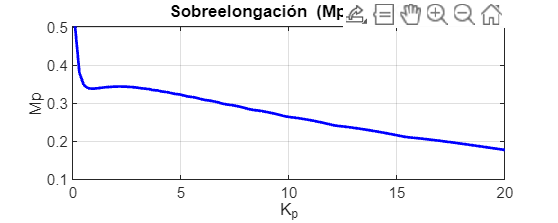




% Barrido de Kp
Kp_vals = linspace(0.1, 20, 100);
% Inicializar métricas
Mp = zeros(size(Kp_vals));
Ts = zeros(size(Kp_vals));
Tr = zeros(size(Kp_vals));
Tp = zeros(size(Kp_vals));

for i = 1:length(Kp_vals)
    Kp = Kp_vals(i);

    num_PID_D = K*Kp*[1, 1/tau_i];
    % Denominador: s^2*(s + p) + controlador
    den_planta = conv([1 0 0], [1 p]);
    den_control = K * Kp * tau_d * [1, 1/tau_d, 1/(tau_d * tau_i)];

    % Igualar tamaños antes de sumar
    n1 = length(den_planta);
    n2 = length(den_control);
    if n1 > n2
        den_control = [zeros(1, n1 - n2), den_control];
    else
        den_planta = [zeros(1, n2 - n1), den_planta];
    end
    den_PID = den_planta + den_control;

    % Sistema en lazo cerrado
    sys = tf(num_PID_D, den_PID);

    % Obtener métricas
    [y, t_out] = step(sys, t);
    info = stepinfo(y, t_out, 'SettlingTimeThreshold', 0.02);
    Mp(i) = info.Peak - 1;
    Ts(i) = info.SettlingTime;
    Tr(i) = info.RiseTime;
    Tp(i) = info.PeakTime;
end

% === Gráfica: Mp vs Kp ===
figure('Units', 'centimeters', 'Position', [2, 2, 20, 8]);
plot(Kp_vals, Mp, 'b', 'LineWidth', 1.5);
xlabel('K_p'); ylabel('Mp');
title('Sobreelongación (Mp) vs K_p'); grid on;

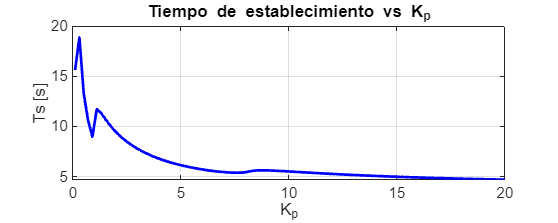


% === Gráfica: Ts vs Kp ===
figure('Units', 'centimeters', 'Position', [2, 2, 20, 8]);
plot(Kp_vals, Ts, 'b', 'LineWidth', 1.5);
xlabel('K_p'); ylabel('Ts [s]');
title('Tiempo de establecimiento vs K_p'); grid on;

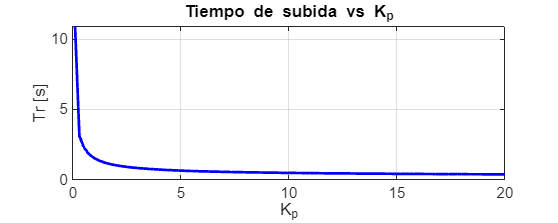


% === Gráfica: Tr vs Kp ===
figure('Units', 'centimeters', 'Position', [2, 2, 20, 8]);
plot(Kp_vals, Tr, 'b', 'LineWidth', 1.5);
xlabel('K_p'); ylabel('Tr [s]');
title('Tiempo de subida vs K_p'); grid on;

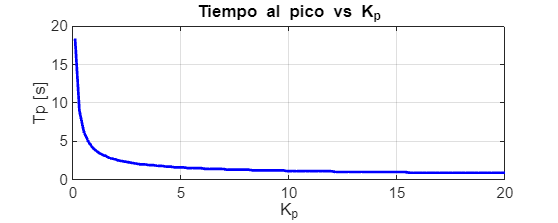


% === Gráfica: Tp vs Kp ===
figure('Units', 'centimeters', 'Position', [2, 2, 20, 8]);
plot(Kp_vals, Tp, 'b', 'LineWidth', 1.5);
xlabel('K_p'); ylabel('Tp [s]');
title('Tiempo al pico vs K_p'); grid on;